clearvars;

nbInterval = 24

nbInterval =     24



abscisse = 2.^(1:nbInterval)

abscisse =            2           4           8          16          32          64         128         256         512        1024        2048        4096        8192       16384       32768       65536      131072      262144      524288     1048576     2097152     4194304     8388608    16777216


errorsS = zeros(nbInterval, 1);
errorsT = zeros(nbInterval, 1);
lastT = -inf;
lastS = -inf;
i= 1;
for n = abscisse

a = 0;
b = pi/2;
% n = 42;
h = (b - a) / n;
x = a:h:b;
y = sin(x);


disp(n)
t = h*((y(1) + y(end))/2 + sum(y(2:end-1)))

s = (h/3) * (y(1) + y(end) + 2 * sum(y(3:2:end-2)) + 4 * sum(y(2:2:end-1)))


func = @(x)  sin(x);

integral(func, 0, pi/2)

errorsT(i) = lastT/(1-t);
errorsS(i) = lastS/(1-s);

lastT = 1-t;
lastS = 1-s;
i = i + 1;
end

     2



t =           0.94805944896852


s =           1.00227987749221


ans =                          1


     4



t =          0.987115800972775


s =           1.00013458497419


ans =                          1


     8



t =           0.99678517188617


s =           1.00000829552397


ans =                          1


    16



t =          0.999196680485072


s =           1.00000051668471


ans =                          1


    32



t =          0.999799194320019


s =             1.000000032265


ans =                          1


    64



t =          0.999949800092101


s =           1.00000000201613


ans =                          1


   128



t =          0.999987450117526


s =             1.000000000126


ans =                          1


   256



t =          0.999996862535288


s =           1.00000000000787


ans =                          1


   512



t =          0.999999215634192


s =           1.00000000000049


ans =                          1


        1024



t =           0.99999980390857


s =           1.00000000000003


ans =                          1


        2048



t =          0.999999950977143


s =                          1


ans =                          1


        4096



t =          0.999999987744288


s =                          1


ans =                          1


        8192



t =          0.999999996936068


s =                          1


ans =                          1


       16384



t =           0.99999999923402


s =          0.999999999999997


ans =                          1


       32768



t =          0.999999999808502


s =                          1


ans =                          1


       65536



t =          0.999999999952134


s =          0.999999999999997


ans =                          1


      131072



t =          0.999999999988033


s =          0.999999999999997


ans =                          1


      262144



t =          0.999999999997002


s =          0.999999999999998


ans =                          1


      524288



t =          0.999999999999259


s =      1


ans =                          1


     1048576



t =          0.999999999999812


s =                          1


ans =                          1


     2097152



t =          0.999999999999943


s =          0.999999999999997


ans =                          1


     4194304



t =                          1


s =          0.999999999999999


ans =                          1


     8388608



t =           1.00000000000003


s =                          1


ans =                          1


    16777216



t =           1.00000000000006


s =           1.00000000000004


ans =                          1


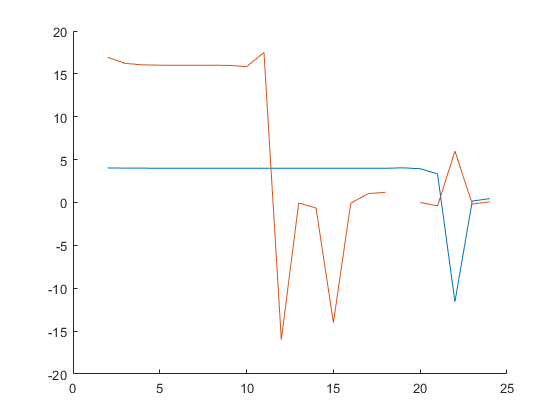


hold on 
plot(1:nbInterval, errorsT)
plot(1:nbInterval, errorsS)
hold off